clear
clc

cc1=@(t) 0*t;
cc2=@(t) 0*t;
ci=@(x) sin(pi*x)

ci = function_handle with value:
    @(x)sin(pi*x)


Tmax=0.5;
alfa=1;


[x,t,U] = calor_implicito(cc1,cc2,ci,0,1,10,Tmax,50,alfa);

solex=exp(-pi^2*0.5)*sin(pi*x);
abs(U(:,end) - solex')

ans =                    0
   0.000675602466541
   0.001285072256458
   0.001768750220287
   0.002079290588948
   0.002186295507493
   0.002079290588948
   0.001768750220287
   0.001285072256458
   0.000675602466541


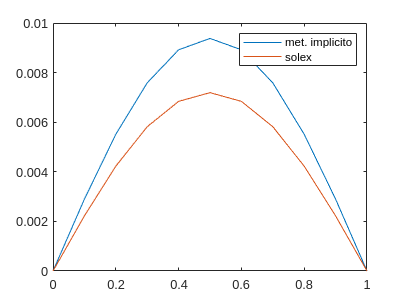

plot(x, U(:,end))
hold on
plot(x, solex)
legend('met. implicito', 'solex')